syms s  Kp Ki l g tau k x

tau_value = 0.103;
k_value = 2.439;
l_value = 0.4822;
g_value = 9.8;
%kp_value = 1.4;
%ki_value = 4.83;

Ms = (k/tau) / (s+(1/tau));
Hs = (-s/l) / (s^2-(g/l));
Ks = Kp + (Ki/s);

transfer_function = ((simplify((1)/(1 - (Hs*Ks*Ms)))));

hello = subs(transfer_function, l, l_value);
hello = subs(hello, k, k_value);
hello = subs(hello, g, g_value);
hello = subs(hello, tau, tau_value);
Ha = hello;


best_val = 0;
best_kp_ki = [0 0];
best_P = [0;0;0];

f = waitbar(0,'1','Name','Finding Values...',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
setappdata(f,'canceling',0);

RANGE_VALS = 25;
total = RANGE_VALS^2;

i = 0;
for kp_i = 1:RANGE_VALS
    val_kp = 1+kp_i*0.01;
    for ki_i = 1:RANGE_VALS
        if getappdata(f,'canceling')
            break
        end
        val_ki = 4+ki_i*0.01;
        Ha = subs(hello, Kp, val_kp);
        Ha = subs(Ha, Ki, val_ki);
        [N, D] = numden(Ha);
        transfer_matlab_form = tf(sym2poly(N), sym2poly(D));
        P = pole(transfer_matlab_form);
        one_real = P(0==imag(P));
        imaginary_vals = P-real(P);
        % check that all are stable
        all_are_stable = (mean(real(P)<=0)==1);
        % check that imaginary values are ~4.5
        imag_correct = sum(round(10.*imaginary_vals)==45i);
        if all_are_stable && imag_correct
            if one_real<best_val
                best_val = one_real;
                best_kp_ki = [val_kp val_ki];
                best_P = P;
            end
        end
        i = i+1;
        waitbar(i/total,f,sprintf('%12.2f',[best_val best_kp_ki]))
    end
end
delete(f)
best_val

best_val = 0

best_kp_ki

best_kp_ki =      0     0


best_P

best_P =      0
     0
     0


kp_value= 1.32

kp_value = 1.3200

ki_value= 4.14

ki_value = 4.1400


Ha = subs(hello, Kp, kp_value);
Ha = subs(Ha, Ki, ki_value);
[N, D] = numden(Ha);
transfer_matlab_form = tf(sym2poly(N), sym2poly(D));
P = pole(transfer_matlab_form)

P =   -4.7850 + 4.5027i
  -4.7850 - 4.5027i
  -0.1387 + 0.0000i


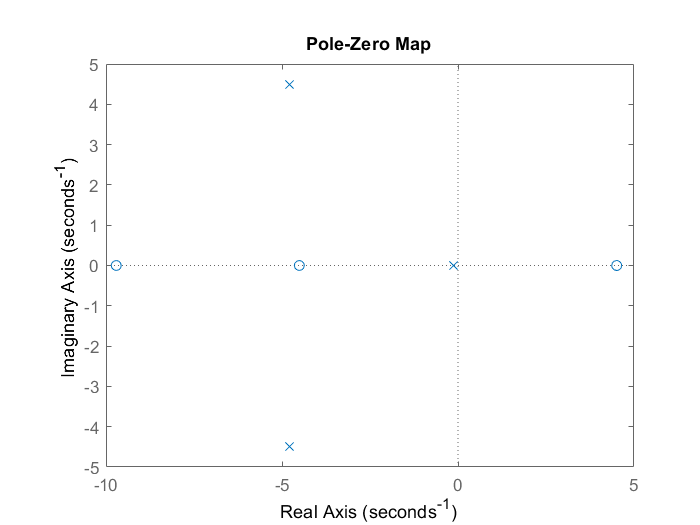


pzplot(transfer_matlab_form)